syms alpha1(t) alpha2(t) alpha3(t) alpha4(t) alpha5(t) T A
syms w1(t) w2(t) w3(t) w4(t) w5(t)
syms theta_c1(t) theta_c2(t) theta_c3(t) theta_c4(t) theta_c5(t) 
assume(T>0)
assume(A>0)
anguloInicialC=-17*pi/180;
anguloFinalC=17*pi/180;
A=2; %rad s^-2
alpha1(t)=10*A/T*t;
alpha2(t)=A;
alpha3(t)=-10*A/T*t;
Calpha3=A-alpha3(4*T/10);
alpha3(t)=alpha3(t)+Calpha3;
alpha4(t)=-A;
alpha5(t)=10*A/T*t;
Calpha5=alpha4(9*T/10)-alpha5(9*T/10);
alpha5(t)=alpha5(t)+Calpha5;
fprintf('Función de aceleración angular:')

Función de aceleración angular:

alpha(t)=piecewise((0<=t<T/10),alpha1,(T/10<=t<4*T/10),alpha2,(4*T/10<=t<6*T/10),alpha3,(6*T/10<=t<9*T/10),alpha4,(9*T/10<=t<=T),alpha5)

$$alpha(t) = \left\{ \begin{array}{cl} \frac{20\,t}{T} & \text{ if }10\,t<T\wedge 0\leq t\\ 2 & \text{ if }T\leq 10\,t\wedge 5\,t<2\,T\\ 10-\frac{20\,t}{T} & \text{ if }5\,t<3\,T\wedge 2\,T\leq 5\,t\\ -2 & \text{ if }10\,t<9\,T\wedge 3\,T\leq 5\,t\\ \frac{20\,t}{T}-20 & \text{ if }t\leq T\wedge 9\,T\leq 10\,t \end{array}\right.$$

w1(t)=int(alpha1);

w2(t)=int(alpha2);
Cw2=w1(T/10)-w2(T/10);
w2(t)=w2(t)+Cw2;

w3(t)=int(alpha3);
Cw3=w2(4*T/10)-w3(4*T/10);
w3(t)=w3(t)+Cw3;

w4(t)=int(alpha4);
Cw4=w3(6*T/10)-w4(6*T/10);
w4(t)=w4(t)+Cw4;

w5(t)=int(alpha5);
Cw5=w4(9*T/10)-w5(9*T/10);
w5(t)=w5(t)+Cw5;
fprintf('Función de velocidad angular:')

Función de velocidad angular:

w(t)=piecewise((0<=t<T/10),w1,(T/10<=t<4*T/10),w2,(4*T/10<=t<6*T/10),w3,(6*T/10<=t<9*T/10),w4,(9*T/10<=t<=T),w5)

$$w(t) = \begin{array}{l} \left\{ \begin{array}{cl} \sigma_{1} & \text{ if }10\,t<T\wedge 0\leq t\\ 2\,t-\frac{T}{10} & \text{ if }T\leq 10\,t\wedge 5\,t<2\,T\\ 10\,t-\frac{17\,T}{10}-\sigma_{1} & \text{ if }5\,t<3\,T\wedge 2\,T\leq 5\,t\\ \frac{19\,T}{10}-2\,t & \text{ if }10\,t<9\,T\wedge 3\,T\leq 5\,t\\ 10\,T-20\,t+\sigma_{1} & \text{ if }t\leq T\wedge 9\,T\leq 10\,t \end{array}\right.\\ \mathrm{where}\\ \sigma_{1}=\frac{10\,t^{2}}{T} \end{array}$$

theta_c1(t)=int(w1)+anguloInicialC;

theta_c2(t)=int(w2);
Ctheta_c2=theta_c1(T/10)-theta_c2(T/10);
theta_c2(t)=theta_c2(t)+Ctheta_c2;

theta_c3(t)=int(w3);
Ctheta_c3=theta_c2(4*T/10)-theta_c3(4*T/10);
theta_c3(t)=theta_c3(t)+Ctheta_c3;

theta_c4(t)=int(w4);
Ctheta_c4=theta_c3(6*T/10)-theta_c4(6*T/10);
theta_c4(t)=theta_c4(t)+Ctheta_c4;

theta_c5(t)=int(w5);
Ctheta_c5=theta_c4(9*T/10)-theta_c5(9*T/10);
theta_c5(t)=theta_c5(t)+Ctheta_c5;
fprintf('Función de desplazamiento angular:')

Función de desplazamiento angular:

Ftheta_c(t)=piecewise((0<=t<T/10),theta_c1,(T/10<=t<4*T/10),theta_c2,(4*T/10<=t<6*T/10),theta_c3,(6*T/10<=t<9*T/10),theta_c4,(9*T/10<=t<=T),theta_c5)

$$Ftheta\_c(t) = \begin{array}{l} \left\{ \begin{array}{cl} \sigma_{1}-\frac{17\,\pi }{180} & \text{ if }10\,t<T\wedge 0\leq t\\ \frac{T^{2}}{300}-\frac{t\,\left(T-10\,t\right)}{10}-\frac{17\,\pi }{180} & \text{ if }T\leq 10\,t\wedge 5\,t<2\,T\\ \frac{13\,T^{2}}{60}-\frac{17\,T\,t}{10}-\frac{17\,\pi }{180}+5\,t^{2}-\sigma_{1} & \text{ if }5\,t<3\,T\wedge 2\,T\leq 5\,t\\ -\frac{151\,T^{2}}{300}+\frac{19\,T\,t}{10}-t^{2}-\frac{17\,\pi }{180} & \text{ if }10\,t<9\,T\wedge 3\,T\leq 5\,t\\ 10\,T\,t-\frac{17\,\pi }{180}-\frac{44\,T^{2}}{15}-10\,t^{2}+\sigma_{1} & \text{ if }t\leq T\wedge 9\,T\leq 10\,t \end{array}\right.\\ \mathrm{where}\\ \sigma_{1}=\frac{10\,t^{3}}{3\,T} \end{array}$$

f=0==Ftheta_c(T/2);
tMax_c=solve(f,T);
fprintf('Tiempo de ciclo %.3f s',tMax_c)

Tiempo de ciclo 1.218 s

alpha=subs(alpha,T,tMax_c);
w=subs(w,T,tMax_c);
Ftheta_c=subs(Ftheta_c,T,tMax_c);

alpha(t)=piecewise((0<=t<tMax_c),alpha(t),(tMax_c<=t<2*tMax_c),-alpha(t-tMax_c))

$$alpha(t) = \begin{array}{l} \left\{ \begin{array}{cl} \sigma_{1} & \text{ if }t\in \left[0,\sigma_{7}\right)\\ 2 & \text{ if }t\in \left[\sigma_{7},\sigma_{8}\right)\\ 10-\sigma_{1} & \text{ if }t\in \left[\sigma_{8},\sigma_{9}\right)\\ -2 & \text{ if }t\in \left[\sigma_{9},\sigma_{5}\right)\\ \sigma_{1}-20 & \text{ if }t\in \left[\sigma_{5},\sigma_{11}\right)\\ -\sigma_{10} & \text{ if }t\in \left[\sigma_{11},\sigma_{3}\right)\\ -2 & \text{ if }t\in \left[\sigma_{3},\sigma_{4}\right)\\ \sigma_{10}-10 & \text{ if }t\in \left[\sigma_{4},\sigma_{6}\right)\\ 2 & \text{ if }t\in \left[\sigma_{6},\sigma_{2}\right)\\ 20-\sigma_{10} & \text{ if }t\in \left[\sigma_{2},\frac{\sqrt{17}\,\sqrt{\pi }}{3}\right) \end{array}\right.\\ \mathrm{where}\\ \sigma_{1}=\frac{120\,\sqrt{17}\,t}{17\,\sqrt{\pi }}\\ \sigma_{2}=\frac{19\,\sqrt{17}\,\sqrt{\pi }}{60}\\ \sigma_{3}=\frac{11\,\sqrt{17}\,\sqrt{\pi }}{60}\\ \sigma_{4}=\frac{7\,\sqrt{17}\,\sqrt{\pi }}{30}\\ \sigma_{5}=\frac{3\,\sqrt{17}\,\sqrt{\pi }}{20}\\ \sigma_{6}=\frac{4\,\sqrt{17}\,\sqrt{\pi }}{15}\\ \sigma_{7}=\frac{\sqrt{17}\,\sqrt{\pi }}{60}\\ \sigma_{8}=\frac{\sqrt{17}\,\sqrt{\pi }}{15}\\ \sigma_{9}=\frac{\sqrt{17}\,\sqrt{\pi }}{10}\\ \sigma_{10}=\frac{120\,\sqrt{17}\,\left(t-\sigma_{11}\right)}{17\,\sqrt{\pi }}\\ \sigma_{11}=\frac{\sqrt{17}\,\sqrt{\pi }}{6} \end{array}$$

w(t)=piecewise((0<=t<tMax_c),w(t),(tMax_c<=t<2*tMax_c),-w(t-tMax_c))

$$w(t) = \begin{array}{l} \left\{ \begin{array}{cl} \sigma_{1} & \text{ if }t\in \left[0,\sigma_{3}\right)\\ 2\,t-\sigma_{3} & \text{ if }t\in \left[\sigma_{3},\sigma_{7}\right)\\ -\sigma_{1}+10\,t-\frac{17\,\sqrt{17}\,\sqrt{\pi }}{60} & \text{ if }t\in \left[\sigma_{7},\sigma_{8}\right)\\ \sigma_{2}-2\,t & \text{ if }t\in \left[\sigma_{8},\sigma_{5}\right)\\ \sigma_{1}-20\,t+\frac{\sigma_{10}}{3} & \text{ if }t\in \left[\sigma_{5},\sigma_{12}\right)\\ -\sigma_{11} & \text{ if }t\in \left[\sigma_{12},\sigma_{4}\right)\\ \frac{\sigma_{9}}{20}-2\,t & \text{ if }t\in \left[\sigma_{4},\frac{\sigma_{9}}{30}\right)\\ \frac{39\,\sqrt{17}\,\sqrt{\pi }}{20}-10\,t+\sigma_{11} & \text{ if }t\in \left[\frac{\sigma_{9}}{30},\sigma_{6}\right)\\ 2\,t-\frac{13\,\sqrt{17}\,\sqrt{\pi }}{20} & \text{ if }t\in \left[\sigma_{6},\sigma_{2}\right)\\ 20\,t-\sigma_{10}-\sigma_{11} & \text{ if }t\in \left[\sigma_{2},\frac{\sqrt{17}\,\sqrt{\pi }}{3}\right) \end{array}\right.\\ \mathrm{where}\\ \sigma_{1}=\frac{60\,\sqrt{17}\,t^{2}}{17\,\sqrt{\pi }}\\ \sigma_{2}=\frac{19\,\sqrt{17}\,\sqrt{\pi }}{60}\\ \sigma_{3}=\frac{\sqrt{17}\,\sqrt{\pi }}{60}\\ \sigma_{4}=\frac{11\,\sqrt{17}\,\sqrt{\pi }}{60}\\ \sigma_{5}=\frac{3\,\sqrt{17}\,\sqrt{\pi }}{20}\\ \sigma_{6}=\frac{4\,\sqrt{17}\,\sqrt{\pi }}{15}\\ \sigma_{7}=\frac{\sqrt{17}\,\sqrt{\pi }}{15}\\ \sigma_{8}=\frac{\sqrt{17}\,\sqrt{\pi }}{10}\\ \sigma_{9}=7\,\sqrt{17}\,\sqrt{\pi }\\ \sigma_{10}=5\,\sqrt{17}\,\sqrt{\pi }\\ \sigma_{11}=\frac{60\,\sqrt{17}\,{\left(t-\sigma_{12}\right)}^{2}}{17\,\sqrt{\pi }}\\ \sigma_{12}=\frac{\sqrt{17}\,\sqrt{\pi }}{6} \end{array}$$

Ftheta_c(t)=piecewise((0<=t<tMax_c),Ftheta_c(t),(tMax_c<=t<2*tMax_c),-Ftheta_c(t-tMax_c))


double(tMax_c)

ans = 1.2180

tMax_c=2*tMax_c

$$tMax\_c = \frac{\sqrt{17}\,\sqrt{\pi }}{3}$$

double(tMax_c)

ans = 2.4360

## Gráficas

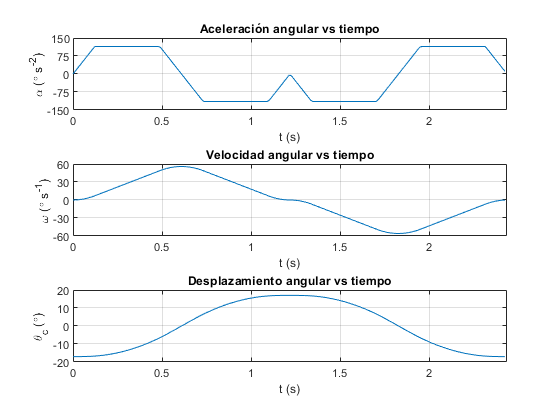

ts=linspace(0,tMax_c,200);
figure()
subplot(3,1,1)
plot(ts,alpha(ts).*180./pi)
title('Aceleración angular vs tiempo')
grid on
xlabel('t (s)')
ylabel('\alpha (\circ s^{-2})')
xlim([0 double(tMax_c)])
ylim([-150 150])
yticks(-150:75:150)

subplot(3,1,2)
plot(ts,w(ts).*180./pi)
title('Velocidad angular vs tiempo')
grid on
xlabel('t (s)')
ylabel('\omega (\circ s^{-1})')
xlim([0 double(tMax_c)])
ylim([-60 60])
yticks(-60:30:60)
subplot(3,1,3)
plot(ts,Ftheta_c(ts).*180./pi)
title('Desplazamiento angular vs tiempo')
grid on
xlabel('t (s)')
ylabel('\theta_c (\circ)')
xlim([0 double(tMax_c)])
ylim([-20 20])
yticks(-20:10:20)

clearvars -except tMax_a tMax_c tMax_b Fz_arfada Fbeta Ftheta_c theta1 P_z C_x C_y D_x D_y D_z L_m L_b L_ub L_bm theta_C beta Z_arfada ArfadaCaso1 ArfadaCaso2 ArfadaCaso3 CabeceoCaso1 CabeceoCaso2 CabeceoCaso3 BalanceoCaso1 BalanceoCaso2 BalanceoCaso3
